N = 30;
% design vector x
% = [torque_Ls, torque_Rs, xs, ys, vs, thetas, thetadots, Tf]
x0 = [zeros(7*N,1); 1];

costfcn = @(x) x(end);

options = optimoptions('fmincon', 'MaxFunctionEvaluations', 1e5, 'Display', 'iter');
xstar = fmincon(costfcn, x0,[],[],[],[],[],[], @nonlcon, options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     212    1.000000e+00    5.000e+00    5.000e-01
    1     424    6.407996e-01    1.907e+00    5.000e-01    2.032e+01
    2     636    6.817213e-01    1.741e+00    5.000e-01    1.391e+00
    3     848    8.210867e-01    1.273e+00    5.000e-01    3.133e+00
    4    1060    1.038395e+00    6.808e-01    5.000e-01    2.311e+00
    5    1272    1.315536e+00    7.872e-04    5.000e-01    2.262e+00
    6    1484    1.357323e+00    1.870e-04    5.000e-01    6.560e-01
    7    1696    1.580441e+00    6.105e-03    5.000e-01    3.617e+00
    8    1908    1.831909e+00    3.948e-03    5.000e-01    2.388e+00
    9    2121    2.319992e+00    1.475e-03    5.000e-01    3.108e+00
   10    2334    2.646324e+00    3.415e-04    3.847e-01    1.612e+00
   11    2547    2.851931e+00    6.646e-05    1.000e-01    8.764e-01
   12    2759    2.294514e+00    1.054e-02    2

xstar =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


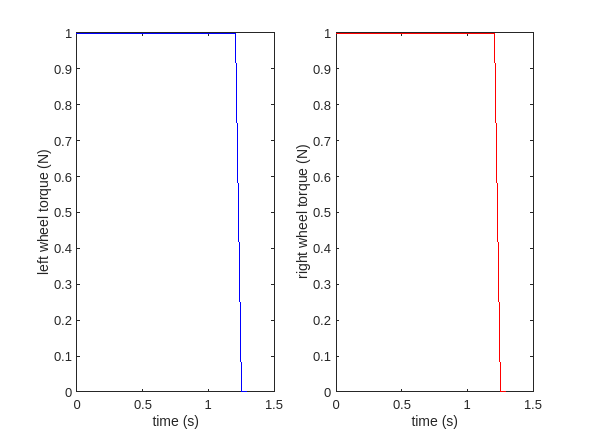


% Extract states from design vector
[ts, tauL, tauR, x, y, v, th, th_dot] = unpack_design_vector(xstar);

% Plot all states and trajectory
figure
hold on
subplot(1, 2, 1);
plot(ts, tauL, 'b-');
xlabel("time (s)")
ylabel("left wheel torque (N)")

subplot(1, 2, 2);
plot(ts, tauR, 'r-');
xlabel("time (s)")
ylabel("right wheel torque (N)")
hold off

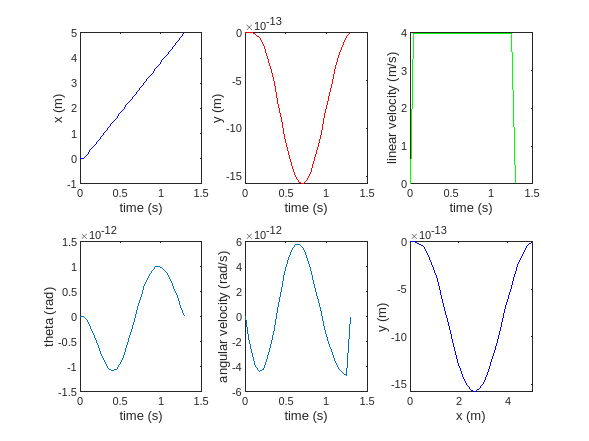


figure
hold on
subplot(2, 3, 1);
plot(ts, x, 'b-');
xlabel("time (s)")
ylabel("x (m)")

subplot(2, 3, 2);
plot(ts, y, 'r-');
xlabel("time (s)")
ylabel("y (m)")

subplot(2, 3, 3);
plot(ts, v, 'g-');
xlabel("time (s)")
ylabel("linear velocity (m/s)")

subplot(2, 3, 4)
plot(ts, th)
xlabel("time (s)")
ylabel("theta (rad)")

subplot(2, 3, 5);
plot(ts, th_dot)
xlabel("time (s)")
ylabel("angular velocity (rad/s)")

subplot(2, 3, 6);
plot(x, y, 'b-');
xlabel("x (m)")
ylabel("y (m)")
hold off

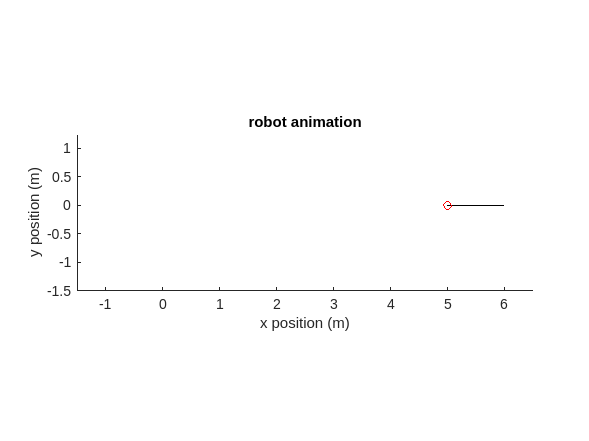


animate_direct_collocation(xstar)